# MaskRCNN Inference(五行 Code)

%Bulit on 2023.4.25 by Fred Liu

Need to Download Support Package：

**Computer Vision Toolbox Model for Mask R-CNN Instance Segmentation**

detector = maskrcnn("resnet50-coco")

detector =   maskrcnn with properties:

      ModelName: 'maskrcnn'
     ClassNames: {1×80 cell}
      InputSize: [800 1200 3]
    AnchorBoxes: [15×2 double]


在resnet50-coco中有80種類別的物件可以辨識

因此這邊載入的是跟YOLOv4 Inference

img = imread('highway.jpg');    

可以調整Threshold的值域

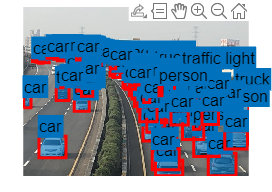

[masks,labels,scores,boxes] = segmentObjects(detector,img,Threshold=0.4);
overlayedImage = insertObjectMask(img,masks);
figure,imshow(overlayedImage)
showShape("rectangle",boxes,Label=labels,LineColor=[1 0 0])